# **MATLAB Code for Lead Calculation and Electrical Axis Plotting**

In this section, a MATLAB code is developed to compute the missing limb lead (Lead II) based on Einthoven's law, and to determine the electrical axis of the heart in the frontal plane. The code allows users to input Q and R wave values for Lead I and Lead III, and subsequently computes the value of Lead II and the corresponding electrical axis angle. Furthermore, the code visualizes these leads and the electrical axis on a standard EKG reference circle to assist in analyzing the heart’s electrical activity.**Overview of the Code Structure**

The MATLAB code is encapsulated within a function named `calculate_lead_and_plot`, which takes four inputs:

- Q and R values of the QRS complex for Lead I.

- Q and R values of the QRS complex for Lead III.

The function calculates the corresponding Lead II using **Einthoven’s law**, and computes the angle of the heart's electrical axis based on the vector components of the input leads. The results are printed and visualized graphically using a unit circle with arrows representing the vectors of Leads I, II, and III. The electrical axis is also plotted as a distinct vector.

main Leads equations

function [lead2, angle_deg] = calculate_lead_and_plot(Q1, R1, Q3, R3)

    % Lead I values (Q1 = Q wave in Lead I, R1 = R wave in Lead I)
    V1 = R1 - Q1;
    
    % Lead III values (Q3 = Q wave in Lead III, R3 = R wave in Lead III)
    V3 = R3 - Q3;
    
    % Einthoven's Law: Lead II = Lead I + Lead III
    lead2 = V1 + V3;
    

The calculations and plotting

    % Calculate the angle of the electrical axis (in degrees)
    angle_rad = atan2(V3, V1);  % Angle in radians
    angle_deg = rad2deg(angle_rad); % Convert to degrees
    
    % Display results
    fprintf('Lead II value: %.2f mV\n', lead2);
    fprintf('Electrical Axis Angle: %.2f degrees\n', angle_deg);
    
    % Plotting the circle and the axes
    theta = linspace(0, 2*pi, 360);
    x_circle = cos(theta);
    y_circle = sin(theta);
    
    % Create the figure
    figure;
    hold on;
    
    % Plot the circle
    plot(x_circle, y_circle, 'b'); 
    
    % Plot the Lead I, Lead II, Lead III axes
    quiver(0, 0, 1, 0, 'MaxHeadSize', 0.2, 'Color', 'g', 'LineWidth', 1.5); % Lead I (0 degrees)
    quiver(0, 0, cosd(60), sind(60), 'MaxHeadSize', 0.2, 'Color', 'g', 'LineWidth', 1.5); % Lead II (+60 degrees)
    quiver(0, 0, cosd(120), sind(120), 'MaxHeadSize', 0.2, 'Color', 'g', 'LineWidth', 1.5); % Lead III (+120 degrees)
    
    % Plot the calculated electrical axis
    quiver(0, 0, cosd(angle_deg), sind(angle_deg), 'MaxHeadSize', 0.4, 'Color', 'r', 'LineWidth', 2); % Electrical axis
    
    % Set axis equal for circular plot
    axis equal;
    
    % Add labels for the leads
    text(1.1, 0, 'Lead I (0°)', 'FontSize', 10);
    text(cosd(60)*1.1, sind(60)*1.1, 'Lead II (+60°)', 'FontSize', 10);
    text(cosd(120)*1.2, sind(120)*1.2, 'Lead III (+120°)', 'FontSize', 10);
    
    % Title and other labels
    xlabel('X');
    ylabel('Y');
    grid on;
    
    hold off;
end

Input and Function section

Lead II value: 1.28 mV
Electrical Axis Angle: 49.47 degrees


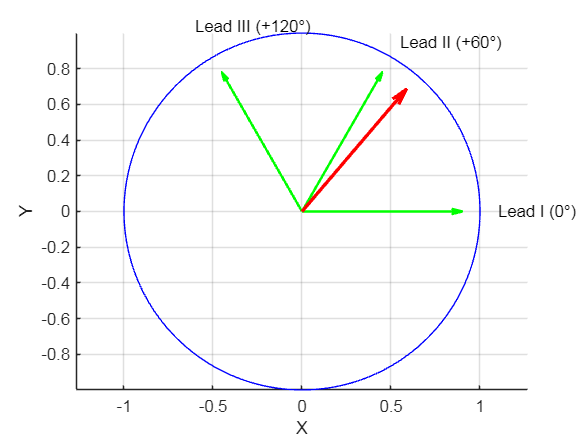

% User input section
Q1 = -0.08;
R1 = 0.51;
Q3 = -0.14;
R3 = 0.55;

% Calculate lead II and the electrical axis angle, and plot the result

[lead2, angle_deg] = calculate_lead_and_plot(Q1, R1, Q3, R3);
